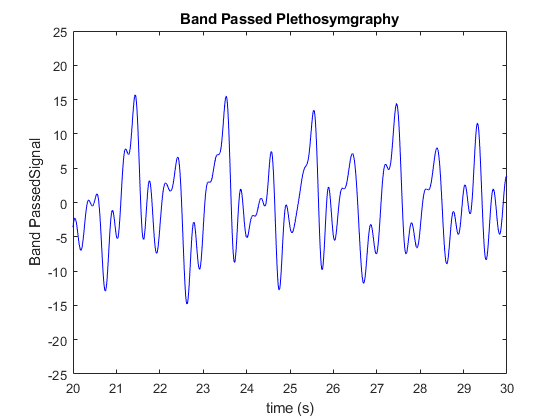

clf;

plethSig = csvread("data.csv");
Fs = 1e3; 
bandPassPlethSig = bandpass(plethSig, [.5 4], Fs);
fftPlethSig = abs((fft(plethSig)));
freq = 0:Fs/length(plethSig):Fs/2; 

time = linspace(0, length(plethSig)/1000, length(plethSig));

figure('Name', 'Percent Difference'); 
plot(time, plethSig, 'r')
hold on;
plot(time, bandPassPlethSig, 'b')
title('Band Passed Plethosymgraphy')
xlim([20 30])
ylim([-25 25])
xlabel('time (s)')
ylabel('Band PassedSignal')
hold off

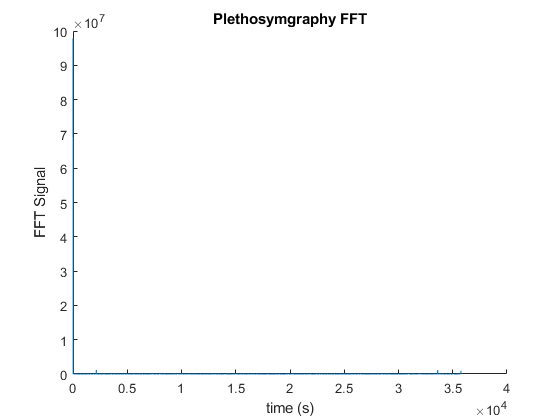


figure 
hold on
plot(fftPlethSig) 
title('Plethosymgraphy FFT')
xlabel('time (s)')
ylabel('FFT Signal')


%figure 
%plot(freq, fftPlethSig, 'g'); 
%title('Plethosymgraphy')
%xlabel('time (s)')
%ylabel('Signal')